clc
clear
close all

Main Script

syms precession nutation spin nutationangle_it1 precessionangle_it1

**Part (b)**

Analytical Solution


a = 0:0.1:8.5 ;
l = (9/4)*a ;

w1_t = cos(l) - (26/45)*(sin(l));
w2_t = (-13/15)*(cos(l)) + (-2/3)*(sin(l)) - (2/15) ;
w3_t = 2 * ones(size(a)); % Create a vector of constant 2 matching t's size

Analytical Plots

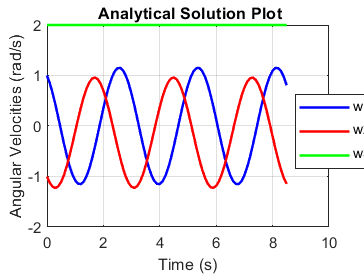

figure;

plot( a, w1_t, 'b', 'LineWidth', 1.5);
hold on;
plot( a, w2_t, 'r', 'LineWidth', 1.5)
hold on;
plot( a, w3_t, 'g', 'LineWidth', 1.5);
legend('w1_t', 'w2_t', 'w3_t', 'Location', 'northeast')
title(' Analytical Solution Plot');
xlabel('Time (s)');
ylabel('Angular Velocities (rad/s)');
grid on;

legend('Position',[0.80941,0.38403,0.23283,0.27464])

Numerical Integration (t = 3 cycles)


% Time span and initial conditions
tspan = 0:.1:13;
statevectorRinitial = [0; 0; 0; 1; 1; -1; 2; 0; 0]; % [q1, q2, q3, q4, w1, w2, w3, wp, wn]

% Solve using ODE45
options = odeset('RelTol', 1e-9, 'AbsTol', 1e-9);
[t, statevectorR] = ode45(@(t, statevectorR) eom(t, statevectorR), tspan, statevectorRinitial, options);

% Extract angular velocities
w1 = statevectorR(:, 5);
w2 = statevectorR(:, 6);
w3 = statevectorR(:, 7);
precession_ode = statevectorR(:,8) ;
nutation_ode = statevectorR(:,9) ; 
precession_deg = rad2deg(precession_ode) ;
nutation_deg = rad2deg(nutation_ode) ;


Ode Plots using t = 0:0.1:8

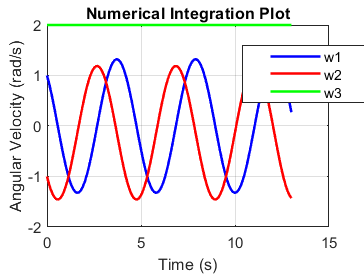


% Plot results for Angular Velocities using Numerical Integration
figure;
plot(t, w1, 'b', 'LineWidth', 1.5);
hold on;
plot(t, w2, 'r', 'LineWidth', 1.5);
plot(t, w3, 'g', 'LineWidth', 1.5);
legend('w1', 'w2', 'w3', 'Location', 'best');
title('Numerical Integration Plot');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
grid on;

legend('Position',[0.80821,0.35394,0.34272,0.20894])

legend('Position',[0.66746,0.62588,0.34931,0.20894])

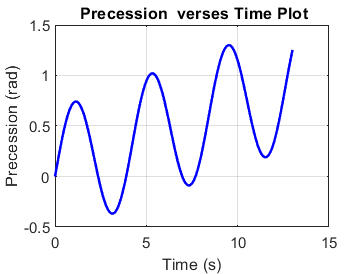


%Plot Results of Angles (Precession and Nutation from the StatevectorR

figure;
plot( tspan, precession_ode, 'b', 'LineWidth', 1.5);
title(' Precession  verses Time Plot');
xlabel('Time (s)');
ylabel('Precession (rad)');
grid on;

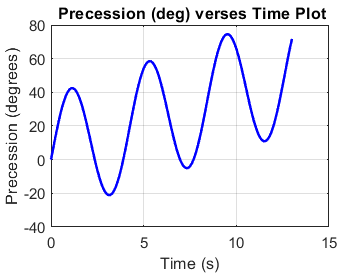


figure;
plot( tspan, precession_deg, 'b', 'LineWidth', 1.5);
title(' Precession (deg) verses Time Plot');
xlabel('Time (s)');
ylabel('Precession (degrees)');
grid on;

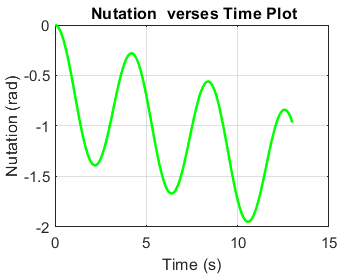


figure;
plot( tspan, nutation_ode, 'g', 'LineWidth', 1.5)
title(' Nutation  verses Time Plot');
xlabel('Time (s)');
ylabel('Nutation (rad)');
grid on;

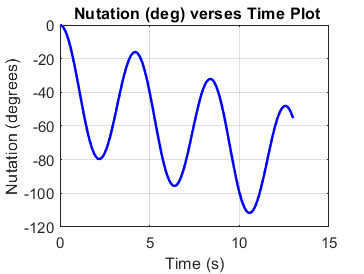

figure;
plot( tspan, nutation_deg, 'b', 'LineWidth', 1.5);
title(' Nutation (deg) verses Time Plot');
xlabel('Time (s)');
ylabel('Nutation (degrees)');
grid on;

**Part (d)**

Numerical Integration ( t = 0:1:12)

% Time span and initial conditions
t_np = 0:.1:12;
statevectorRinitial = [0; 0; 0; 1; 1; -1; 2; 0; 0]; % [q1, q2, q3, q4, w1, w2, w3, wp, wn]

% Solve using ODE45
options = odeset('RelTol', 1e-9, 'AbsTol', 1e-9);
[t, statevectorR] = ode45(@(t, statevectorR) eom(t, statevectorR), t_np, statevectorRinitial, options);

%Extract quarternions
q1 = statevectorR(:,1) 

q1 =          0
    0.0466
    0.0856
    0.1162
    0.1377
    0.1496
    0.1516
    0.1437
    0.1261
    0.0993


q2 = statevectorR(:,2) 

q2 =          0
   -0.0536
   -0.1135
   -0.1784
   -0.2469
   -0.3174
   -0.3885
   -0.4584
   -0.5258
   -0.5890


q3 = statevectorR(:,3)

q3 =          0
    0.0996
    0.1971
    0.2901
    0.3766
    0.4547
    0.5226
    0.5787
    0.6218
    0.6510


q4 = statevectorR(:,4)

q4 =     1.0000
    0.9925
    0.9700
    0.9330
    0.8822
    0.8186
    0.7436
    0.6590
    0.5666
    0.4685



% Extract angular velocities
w1 = statevectorR(:, 5)

w1 =     1.0000
    0.8593
    0.6992
    0.5235
    0.3360
    0.1409
   -0.0573
   -0.2542
   -0.4454
   -0.6266


w2 = statevectorR(:, 6)

w2 =    -1.0000
   -1.1397
   -1.2568
   -1.3487
   -1.4133
   -1.4491
   -1.4554
   -1.4320
   -1.3794
   -1.2989


w3 = statevectorR(:, 7)

w3 =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2



%Extract Angles
precession_ode = statevectorR(:,8) ;
nutation_ode = statevectorR(:,9) ; 
precession_deg = rad2deg(precession_ode) 

precession_deg =          0
    5.7381
   11.4132
   16.9063
   22.1026
   26.8940
   31.1816
   34.8775
   37.9074
   40.2118


nutation_deg = rad2deg(nutation_ode) 

nutation_deg =          0
   -0.4017
   -1.6037
   -3.5874
   -6.3169
   -9.7396
  -13.7870
  -18.3769
  -23.4148
  -28.7961


DCM 

c11 = 1 - 2.*((statevectorR(:,2)).^2) - 2.*((statevectorR(:,3)).^2) ;
c12 = 2.*( (statevectorR(:,1).*statevectorR(:,2)) - (statevectorR(:,3).*statevectorR(:,4)) ) ;
c13 = 2.*( (statevectorR(:,1).*statevectorR(:,3)) + (statevectorR(:,2).*statevectorR(:,4)) ) ;
c21 = 2.*( (statevectorR(:,1).*statevectorR(:,2)) + (statevectorR(:,3).*statevectorR(:,4)) ) ;
c22 = 1 - 2.*((statevectorR(:,1)).^2) - 2.*((statevectorR(:,3)).^2) ;
c23 =  2.*( (statevectorR(:,2).*statevectorR(:,3)) - (statevectorR(:,1).*statevectorR(:,4)) ) ;
c31 = 2.*( (statevectorR(:,1).*statevectorR(:,3)) - (statevectorR(:,2).*statevectorR(:,4)) ) ;
c32 = 2.*( (statevectorR(:,2).*statevectorR(:,3)) - (statevectorR(:,2).*statevectorR(:,1)) ) ;
c33 = 1 - 2.*((statevectorR(:,1)).^2) - 2.*((statevectorR(:,2)).^2) ;

%DCM = [c11 c12 c13; c21 c22 c23; c31 c32 c33] ;

Plot (t = 0:1:12)

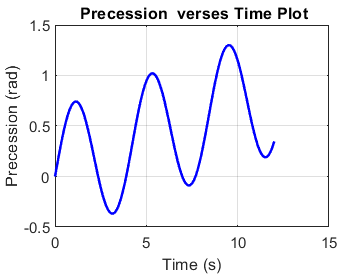

%Plot Results of Angles (Precession and Nutation from the StatevectorR

figure;
plot( t_np, precession_ode, 'b', 'LineWidth', 1.5);
title(' Precession  verses Time Plot');
xlabel('Time (s)');
ylabel('Precession (rad)');
grid on;

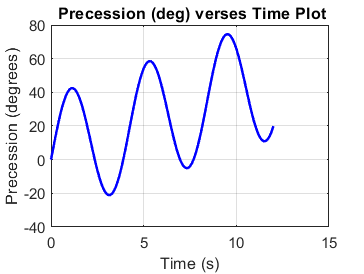


figure;
plot( t_np, precession_deg, 'b', 'LineWidth', 1.5);
title(' Precession (deg) verses Time Plot');
xlabel('Time (s)');
ylabel('Precession (degrees)');
grid on;

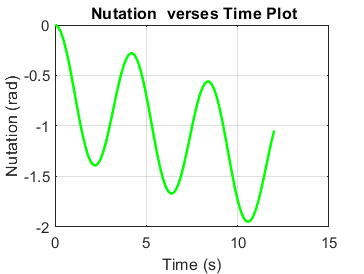


figure;
plot( t_np, nutation_ode, 'g', 'LineWidth', 1.5)
title(' Nutation  verses Time Plot');
xlabel('Time (s)');
ylabel('Nutation (rad)');
grid on;

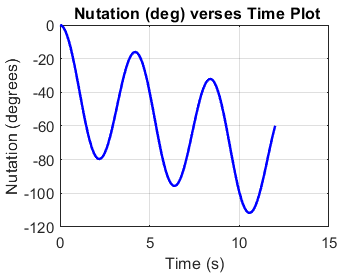

figure;
plot( t_np, nutation_deg, 'b', 'LineWidth', 1.5);
title(' Nutation (deg) verses Time Plot');
xlabel('Time (s)');
ylabel('Nutation (degrees)');
grid on;

Updated CODE for part (d)

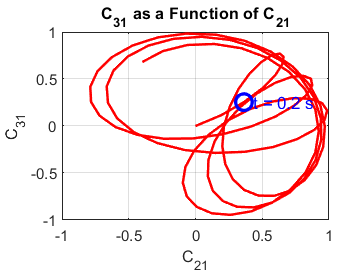

% Plot C31 vs C21
figure;
plot(c21, c31, 'r', 'LineWidth', 1.5);
hold on;

% Mark the point corresponding to t = 0.2 s
[~, t_idx] = min(abs(t - 0.2)); % Find index closest to t = 0.2 s
plot(c21(t_idx), c31(t_idx), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
text(c21(t_idx), c31(t_idx), '  t = 0.2 s', 'FontSize', 10, 'Color', 'b');

% Add labels and grid
title('C_{31} as a Function of C_{21}');
xlabel('C_{21}');
ylabel('C_{31}');
grid on;
axis([-1 1 -1 1]); % Ensure the plot stays within the range [-1, 1]


% Calculate precession at t = 0.2 s (from DCM or precomputed values)
precession_at_t = precession_ode(t_idx);
disp(['Precession angle at t = 0.2 s: ', num2str(precession_at_t), ' rad']);

Precession angle at t = 0.2 s: 0.1992 rad


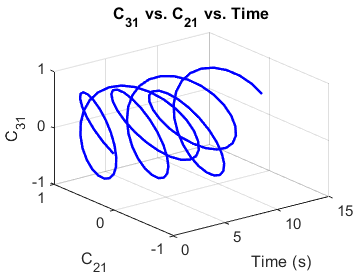



for i = 1:t_np
    q_i = q(i, :)';  % Extract quaternion at step i
    q_i = q_i / norm(q_i);  % Normalize quaternion (if needed)
    C = quat_to_dcm(q_i);  % Compute DCM

    % Extract relevant direction cosines
    c21(i) = C(2, 1);
    c31(i) = C(3, 1);
end

figure;
plot3(t, c21, c31, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('C_{21}');
zlabel('C_{31}');
title('C_{31} vs. C_{21} vs. Time');
grid on;

**ChatGPT edit Updated C13 vs C23**

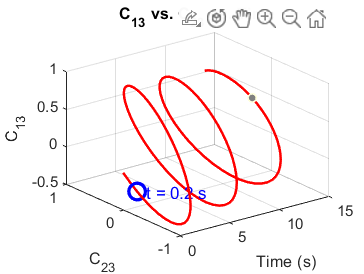

% C23 vs C13 over time
figure;
plot3(t_np, c23, c13, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('C_{23}');
zlabel('C_{13}');
title('C_{13} vs. C_{23} vs. Time');
grid on;
hold on;  % Hold on to add more plots to the current figure

% Mark the point corresponding to t = 0.2 s
[~, t_idx] = min(abs(t_np - 0.2));  % Find index closest to t = 0.2 s
plot3(t_np(t_idx), c23(t_idx), c13(t_idx), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
text(t_np(t_idx), c23(t_idx), c13(t_idx), '  t = 0.2 s', 'FontSize', 10, 'Color', 'b');

hold off;  % Release the figure

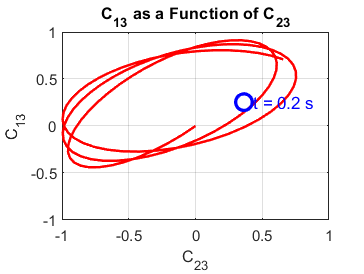



% Plot C23 vs C13
figure;
plot(c23, c13, 'r', 'LineWidth', 1.5);
hold on;

% Mark the point corresponding to t = 0.2 s
[~, t_idx] = min(abs(t_np - 0.2)); % Find index closest to t = 0.2 s
plot(c21(t_idx), c31(t_idx), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
text(c21(t_idx), c31(t_idx), '  t = 0.2 s', 'FontSize', 10, 'Color', 'b');

% Add labels and grid
title('C_{13} as a Function of C_{23}');
xlabel('C_{23}');
ylabel('C_{13}');
grid on;
axis([-1 1 -1 1]); % Ensure the plot stays within the range [-1, 10]

3-1-3 Rotation

c1 = cosd(precession) ; s1 = sind(precession)

$$s1 = \sin\left(\frac{\pi \,\mathrm{precession}}{180}\right)$$

c2 = cosd(nutation) ; s2 = sind(nutation) 

$$s2 = \sin\left(\frac{\pi \,\mathrm{nutation}}{180}\right)$$

c3 = cosd(spin) ; s3 = sind(spin) 

$$s3 = \sin\left(\frac{\pi \,\mathrm{spin}}{180}\right)$$


DCM_unknown = [c1*c3 - c2*s1*s3, - c1*s3 - c2*c3*s1,  s1*s2; c3*s1 + c1*c2*s3,   c1*c2*c3 - s1*s3, -c1*s2;  s2*s3,   c3*s2,     c2]  ;

Function Code

function drdt = eom(t, statevectorR)

    % Constants
    C = 100; A = 400; T = 80;

    % Extract state variables
    q = statevectorR(1:3);  % Quaternion vector (x, y, z)
    q4 = statevectorR(4);   % Scalar part of quaternion
    w = statevectorR(5:7);  % Angular velocities (w1, w2, w3)
   
    % Quaternion kinematics
    qdot = 0.5 * (q4 * w + cross(q, w));
    q4dot = -0.5 * dot(w, q);

    % Angular velocity dynamics
    w1dot = (T / A) + ((A - C) / A) * w(2) * w(3);
    w2dot = ((C - A) / A) * w(1) * w(3);
    w3dot = 0;

    % Precession and nutation dynamics
    wn = 0.5.*(w(1) + w(2));
    wp =  w(1) - (0.5.*(w(1) + w(2))) ;

    % Combine derivatives into a column vector
    drdt = [qdot; q4dot; w1dot; w2dot; w3dot; wp; wn];
end